## Q3 - part a | Box-Jenkins

clc; clear;


%%

load q3_402123100.mat

u1_val = u2;
y1_val = y2;

u2_val = u1;
y2_val = y1;


### Guassian Input - PRBS Validation


%%
% Guassian Input **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> Guassian Input Identification Begins:------------------------------\n")

>>> Guassian Input Identification Begins:------------------------------



Ts = 0.1;
t = 0:Ts:length(u1)*Ts-Ts;
t_val = 0:Ts:length(u1_val)*Ts-Ts;
N = length(y1);
N_val = length(y1_val);

data_guassian = iddata(y1,u1,Ts);

%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nd = degree;
    nk = 1;
    p = na+nb+nc+nd;
    
    try
        sys = bj(data_guassian, [na nb nc nd nk]);
        bj_y_hat_guassian = lsim(sys, u1, t);
    catch
        break
    end

    [r2_bj, mse_bj] = rSQR(y1, bj_y_hat_guassian);

    error = y1 - bj_y_hat_guassian;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_bj, mse_bj, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_bj];
    MSEs = [MSEs; mse_bj];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.894672 | MSE=0.028346 | var=0.028374 | s_hat=116.104729 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.941005 | MSE=0.015877 | var=0.015908 | s_hat=65.031084 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.941010 | MSE=0.015875 | var=0.015922 | s_hat=65.025778 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.941099 | MSE=0.015852 | var=0.015914 | s_hat=64.928113 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.941110 | MSE=0.015848 | var=0.015926 | s_hat=64.915253 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.941118 | MSE=0.015846 | var=0.015940 | s_hat=64.907134 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.941177 | MSE=0.015831 | var=0.015940 | s_hat=64.842113 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.941097 | MSE=0.015852 | var=0.015977 | s_hat=64.930430 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.941133 | MSE=0.015842 | var=0.015983 | s_hat=64.889790 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.941158 | MSE=0.015836 | var=0.015992 | s_hat=64.863000 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.941375 | MSE=0.015777 | var=0.015949 | s_hat=64.623509 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.941307 | MSE=0.015795 | var=0.015983 | s_hat=64.698110 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.941359 | MSE=0.015782 | var=0.015984 | s_hat=64.641187 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.940769 | MSE=0.015940 | var=0.016161 | s_hat=65.291153 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.941451 | MSE=0.015757 | var=0.015991 | s_hat=64.539167 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.926402 | MSE=0.019807 | var=0.020121 | s_hat=81.128693 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.941221 | MSE=0.015819 | var=0.016086 | s_hat=64.793186 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.941588 | MSE=0.015720 | var=0.016001 | s_hat=64.388373 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.941515 | MSE=0.015740 | var=0.016037 | s_hat=64.469124 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.940124 | MSE=0.016114 | var=0.016435 | s_hat=66.002875 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.940079 | MSE=0.016126 | var=0.016464 | s_hat=66.051870 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.940512 | MSE=0.016009 | var=0.016361 | s_hat=65.574732 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.941676 | MSE=0.015696 | var=0.016057 | s_hat=64.291152 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.941848 | MSE=0.015650 | var=0.016025 | s_hat=64.101610 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.941848 | MSE=0.015650 | var=0.016041 | s_hat=64.101808 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.937915 | MSE=0.016708 | var=0.017144 | s_hat=68.436964 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.942045 | MSE=0.015597 | var=0.016019 | s_hat=63.884493 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.929190 | MSE=0.019056 | var=0.019592 | s_hat=78.054811 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.858947 | MSE=0.037960 | var=0.039067 | s_hat=155.485789 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.940473 | MSE=0.016020 | var=0.016503 | s_hat=65.617737 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.941115 | MSE=0.015847 | var=0.016342 | s_hat=64.910047 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.921220 | MSE=0.021201 | var=0.021885 | s_hat=86.840888 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.871403 | MSE=0.034608 | var=0.035761 | s_hat=141.755397 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.940141 | MSE=0.016109 | var=0.016663 | s_hat=65.983934 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.897716 | MSE=0.027527 | var=0.028501 | s_hat=112.749526 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.940826 | MSE=0.015925 | var=0.016505 | s_hat=65.229182 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.926601 | MSE=0.019753 | var=0.020494 | s_hat=80.908898 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.942005 | MSE=0.015608 | var=0.016209 | s_hat=63.928887 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.921887 | MSE=0.021022 | var=0.021854 | s_hat=86.105920 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.942010 | MSE=0.015606 | var=0.016241 | s_hat=63.923070 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.936417 | MSE=0.017111 | var=0.017825 | s_hat=70.088585 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.941881 | MSE=0.015641 | var=0.016310 | s_hat=64.065974 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.591534 | MSE=0.109927 | var=0.114745 | s_hat=450.260120 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.939003 | MSE=0.016415 | var=0.017152 | s_hat=67.237665 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.925574 | MSE=0.020030 | var=0.020950 | s_hat=82.041707 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.848802 | MSE=0.040691 | var=0.042604 | s_hat=166.668434 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.822998 | MSE=0.047635 | var=0.049926 | s_hat=195.112716 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.902232 | MSE=0.026311 | var=0.027605 | s_hat=107.771573 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.941560 | MSE=0.015727 | var=0.016518 | s_hat=64.419319 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.891222 | MSE=0.029274 | var=0.030777 | s_hat=119.908333 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.840460 | MSE=0.042936 | var=0.045186 | s_hat=175.864079 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.938161 | MSE=0.016642 | var=0.017533 | s_hat=68.166463 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.920739 | MSE=0.021331 | var=0.022495 | s_hat=87.370763 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=-5.004821 | MSE=1.616023 | var=1.705987 | s_hat=6619.231038 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.937095 | MSE=0.016929 | var=0.017890 | s_hat=69.341368 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=-0.259309 | MSE=0.338906 | var=0.358513 | s_hat=1388.160777 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.891399 | MSE=0.029227 | var=0.030950 | s_hat=119.712781 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.872470 | MSE=0.034321 | var=0.036382 | s_hat=140.578469 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.134289 | MSE=0.232981 | var=0.247225 | s_hat=954.290285 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.663598 | MSE=0.090533 | var=0.096168 | s_hat=370.822839 | 


-------------------------------------------------------------



fprintf("=================================================================\n")



%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 27 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
nd = bestFitDegree;
nk = 1;
p = na+nb+nc+nd;

BestFitModel_guassian = bj(data_guassian, [na nb nc nd nk])

BestFitModel_guassian =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                          
                                                                                                          
  B(z) = 0.3951 z^-1 - 0.3933 z^-2 + 0.1126 z^-3 + 0.2073 z^-4 - 0.4613 z^-5 + 0.2168 z^-6 + 0.05889 z^-7 
          + 4.516e-05 z^-8 - 0.003104 z^-9 + 0.123 z^-10 - 0.1812 z^-11 - 0.09866 z^-12 + 0.2483 z^-13    
          - 0.2612 z^-14 + 0.2311 z^-15 + 0.02441 z^-16 - 0.1135 z^-17 - 0.01194 z^-18 + 0.01868 z^-19    
          - 0.04686 z^-20 - 0.0823 z^-21 + 0.4258 z^-22 - 0.386 z^-23 + 0.04364 z^-24 + 0.1802 z^-25      
                                                                        - 0.3443 z^-26 + 0.1109 z^-27     
                                                                                                          
                                                                                                          
  C(z) = 1 + 

BestFit_y_hat_guassian = lsim(BestFitModel_guassian, u1_val, t_val);
% [bj_BestFit_r2, bj_BestFit_mse] = rSQR(y_val, BestFit_y_hat);

%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 2 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 2 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
nd = minVarIndex;
nk = 1;
p = na+nb+nc+nd;

bj_VarModel_guassian = bj(data_guassian, [na nb nc nd nk])

bj_VarModel_guassian =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = 0.3949 z^-1 - 0.1838 z^-2                              
                                                                
  C(z) = 1 + 0.1904 z^-1 - 0.263 z^-2                           
                                                                
  D(z) = 1 + 0.017 z^-1 - 0.372 z^-2                            
                                                                
  F(z) = 1 - 1.143 z^-1 + 0.4335 z^-2                           
                                                                
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using BJ on time domain data "data_guassian".
Fit to estimation data: 76.27% (prediction focus)      
FPE: 0.

Var_y_hat_guassian = lsim(bj_VarModel_guassian, u1_val, t_val);
% [bj_Var_r2, bj_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 2 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 2 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
nd = minAICIndex;
nk = 1;
p = na+nb+nc+nd;

bj_AICModel_guassian = bj(data_guassian, [na nb nc nd nk])

bj_AICModel_guassian =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = 0.3949 z^-1 - 0.1838 z^-2                              
                                                                
  C(z) = 1 + 0.1904 z^-1 - 0.263 z^-2                           
                                                                
  D(z) = 1 + 0.017 z^-1 - 0.372 z^-2                            
                                                                
  F(z) = 1 - 1.143 z^-1 + 0.4335 z^-2                           
                                                                
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using BJ on time domain data "data_guassian".
Fit to estimation data: 76.27% (prediction focus)      
FPE: 0.

AIC_y_hat_guassian = lsim(bj_AICModel_guassian, u1_val, t_val);
% [bj_AIC_r2, bj_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.16 as


fprintf("    Degree = %d \n", winner)

    Degree = 2 



na = winner;
nb = winner;
nc = winner;
nd = winner;
nk = 1;
p = na+nb+nc+nd;

bj_FTestModel_guassian = bj(data_guassian, [na nb nc nd nk])

bj_FTestModel_guassian =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = 0.3949 z^-1 - 0.1838 z^-2                              
                                                                
  C(z) = 1 + 0.1904 z^-1 - 0.263 z^-2                           
                                                                
  D(z) = 1 + 0.017 z^-1 - 0.372 z^-2                            
                                                                
  F(z) = 1 - 1.143 z^-1 + 0.4335 z^-2                           
                                                                
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using BJ on time domain data "data_guassian".
Fit to estimation data: 76.27% (prediction focus)      
FPE: 

FTest_y_hat_guassian = lsim(bj_FTestModel_guassian, u1_val, t_val);
% [bj_FTest_r2, bj_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")



%%

[bj_BestFit_r2_guassian, bj_BestFit_mse_guassian] = rSQR(y1_val, BestFit_y_hat_guassian);
[bj_Var_r2_guassian, bj_Var_mse_guassian] = rSQR(y1_val, Var_y_hat_guassian);
[bj_AIC_r2_guassian, bj_AIC_mse_guassian] = rSQR(y1_val, AIC_y_hat_guassian);
[bj_FTest_r2_guassian, bj_FTest_mse_guassian] = rSQR(y1_val, FTest_y_hat_guassian);

%%

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_BestFit_r2_guassian, bj_BestFit_mse_guassian)

    R2 value : 0.9422   | MSE : 0.0154 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Var_r2_guassian, bj_Var_mse_guassian)

    R2 value : 0.9431   | MSE : 0.0152 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Cov_r2, bj_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_AIC_r2_guassian, bj_AIC_mse_guassian)

    R2 value : 0.9431   | MSE : 0.0152 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_FTest_r2_guassian, bj_FTest_mse_guassian)

    R2 value : 0.9431   | MSE : 0.0152 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

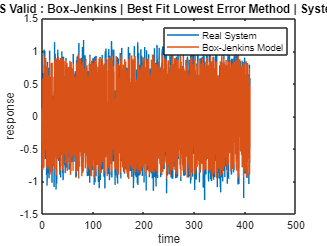



%%

% bj_BestFitError_guassian = y1_val - BestFit_y_hat_guassian;
% bj_VarError_guassian = y1_val - Var_y_hat_guassian;
% bj_AICError_guassian = y1_val - AIC_y_hat_guassian;
% bj_FTestError_guassian = y1_val - FTest_y_hat_guassian;
% 
% for k=0:N_val-1
%     bj_BestFit_Ree_guassian(k+1,1) = AutoCorrelate(bj_BestFitError_guassian, k);
%     bj_Var_Ree_guassian(k+1,1) = AutoCorrelate(bj_VarError_guassian, k);
%     bj_AIC_Ree_guassian(k+1,1) = AutoCorrelate(bj_AICError_guassian, k);
%     bj_FTest_Ree_guassian(k+1,1) = AutoCorrelate(bj_FTestError_guassian, k);
% end
% 
% for k=0:N_val-1
%     bj_BestFit_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, bj_BestFitError_guassian, k);
%     bj_Var_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, bj_VarError_guassian, k);
%     bj_AIC_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, bj_AICError_guassian, k);
%     bj_FTest_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, bj_FTestError_guassian, k);
% end


%%
figure(1)
plot(t_val,y1_val,t_val,BestFit_y_hat_guassian)
legend('Real System','Box-Jenkins Model')
title(" Guassian Ident - PRBS Valid : Box-Jenkins | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

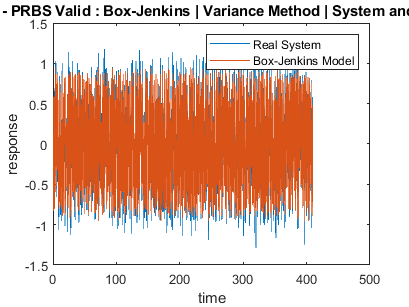


figure(2)
plot(t_val,y1_val,t_val,Var_y_hat_guassian)
legend('Real System','Box-Jenkins Model')
title(" Guassian Ident - PRBS Valid : Box-Jenkins | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

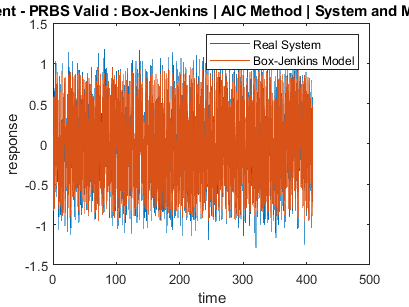


figure(3)
plot(t_val,y1_val,t_val,AIC_y_hat_guassian)
legend('Real System','Box-Jenkins Model')
title(" Guassian Ident - PRBS Valid : Box-Jenkins | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

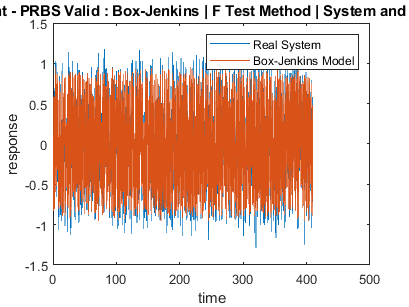


figure(4)
plot(t_val,y1_val,t_val,FTest_y_hat_guassian)
legend('Real System','Box-Jenkins Model')
title(" Guassian Ident - PRBS Valid : Box-Jenkins | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")


%%

% figure(5)
% subplot(4,1,1)
% plot(1:N_val-1,bj_BestFit_Ree_guassian(2:end), 1:N_val-1, mean(bj_BestFit_Ree_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Box-Jenkins | Best Fit Lowest Errror Method | Ree_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_guassian(k)")
% 
% subplot(4,1,2)
% plot(1:N_val-1,bj_Var_Ree_guassian(2:end), 1:N_val-1, mean(bj_Var_Ree_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Box-Jenkins | Variance Method | Ree_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_guassian(k)")
% 
% subplot(4,1,3)
% plot(1:N_val-1,bj_AIC_Ree_guassian(2:end), 1:N_val-1, mean(bj_AIC_Ree_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Box-Jenkins | AIC Method | Ree_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_guassian(k)")
% 
% subplot(4,1,4)
% plot(1:N_val-1,bj_FTest_Ree_guassian(2:end), 1:N_val-1, mean(bj_FTest_Ree_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Box-Jenkins | F Test Method | Ree_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_guassian(k)")

%%

% figure(6)
% subplot(4,1,1)
% plot(1:N_val-1,bj_BestFit_Rue_guassian(2:end), 1:N_val-1, mean(bj_BestFit_Rue_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Box-Jenkins | Best Fit Lowest Errror Method | Rue_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_guassian(k)")
% 
% subplot(4,1,2)
% plot(1:N_val-1,bj_Var_Rue_guassian(2:end), 1:N_val-1, mean(bj_Var_Rue_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Box-Jenkins | Variance Method | Rue_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_guassian(k)")
% 
% subplot(4,1,3)
% plot(1:N_val-1,bj_AIC_Rue_guassian(2:end), 1:N_val-1, mean(bj_AIC_Rue_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Box-Jenkins | AIC Method | Rue_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_guassian(k)")
% 
% subplot(4,1,4)
% plot(1:N_val-1,bj_FTest_Rue_guassian(2:end), 1:N_val-1, mean(bj_FTest_Rue_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Box-Jenkins | F Test Method | Rue_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_guassian(k)")



### PRBS Input - Guassian Validation


%%
% PRBS Input **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> PRBS Input Identification Begins:------------------------------\n")

>>> PRBS Input Identification Begins:------------------------------



%%

Ts = 0.1; 
t = 0:Ts:length(u2)*Ts-Ts;
t_val = 0:Ts:length(u2_val)*Ts-Ts;
N = length(y2);
N_val = length(y2_val);

data_prbs = iddata(y2,u2,Ts);

%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nd = degree;
    nk = 1;
    p = na+nb+nc+nd;
    
    try
        sys = bj(data_prbs, [na nb nc nd nk]);
        bj_y_hatprbs = lsim(sys, u2, t);
    catch
        break
    end

    [r2_bj, mse_bj] = rSQR(y2, bj_y_hatprbs);

    error = y2 - bj_y_hatprbs;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_bj, mse_bj, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_bj];
    MSEs = [MSEs; mse_bj];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.896389 | MSE=0.027613 | var=0.027640 | s_hat=113.103267 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.943231 | MSE=0.015129 | var=0.015159 | s_hat=61.969486 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.943297 | MSE=0.015112 | var=0.015156 | s_hat=61.898301 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.943361 | MSE=0.015095 | var=0.015154 | s_hat=61.828175 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.943379 | MSE=0.015090 | var=0.015164 | s_hat=61.808049 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.943435 | MSE=0.015075 | var=0.015164 | s_hat=61.747231 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.943455 | MSE=0.015070 | var=0.015173 | s_hat=61.725250 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.943352 | MSE=0.015097 | var=0.015216 | s_hat=61.837477 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.943539 | MSE=0.015047 | var=0.015181 | s_hat=61.634183 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.905857 | MSE=0.025090 | var=0.025337 | s_hat=102.768328 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.943664 | MSE=0.015014 | var=0.015177 | s_hat=61.496977 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.943480 | MSE=0.015063 | var=0.015242 | s_hat=61.698586 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.943712 | MSE=0.015001 | var=0.015194 | s_hat=61.445042 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.943413 | MSE=0.015081 | var=0.015290 | s_hat=61.770971 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.943776 | MSE=0.014984 | var=0.015207 | s_hat=61.374935 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.934303 | MSE=0.017509 | var=0.017787 | s_hat=71.716109 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.939729 | MSE=0.016063 | var=0.016334 | s_hat=65.792462 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.943913 | MSE=0.014948 | var=0.015215 | s_hat=61.225653 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.938134 | MSE=0.016488 | var=0.016800 | s_hat=67.534332 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.943830 | MSE=0.014970 | var=0.015268 | s_hat=61.316324 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.943978 | MSE=0.014930 | var=0.015243 | s_hat=61.155006 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.832246 | MSE=0.044708 | var=0.045689 | s_hat=183.123154 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.944084 | MSE=0.014902 | var=0.015245 | s_hat=61.039311 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.943937 | MSE=0.014941 | var=0.015300 | s_hat=61.199052 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.940315 | MSE=0.015906 | var=0.016305 | s_hat=65.152821 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.942278 | MSE=0.015383 | var=0.015784 | s_hat=63.010340 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.938508 | MSE=0.016388 | var=0.016832 | s_hat=67.125439 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.790265 | MSE=0.055896 | var=0.057467 | s_hat=228.949826 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.938130 | MSE=0.016489 | var=0.016969 | s_hat=67.538610 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.646850 | MSE=0.094117 | var=0.096958 | s_hat=385.504304 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.944309 | MSE=0.014842 | var=0.015306 | s_hat=60.793782 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.944011 | MSE=0.014921 | var=0.015403 | s_hat=61.118165 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.944117 | MSE=0.014893 | var=0.015389 | s_hat=61.002983 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.937615 | MSE=0.016626 | var=0.017197 | s_hat=68.100933 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.799565 | MSE=0.053418 | var=0.055308 | s_hat=218.798181 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.930257 | MSE=0.018587 | var=0.019264 | s_hat=76.132524 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=-1.862377 | MSE=0.762847 | var=0.791444 | s_hat=3124.619859 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.942931 | MSE=0.015209 | var=0.015795 | s_hat=62.297265 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.943058 | MSE=0.015176 | var=0.015776 | s_hat=62.159180 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.936673 | MSE=0.016877 | var=0.017563 | s_hat=69.129093 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.851150 | MSE=0.039670 | var=0.041324 | s_hat=162.486725 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.943493 | MSE=0.015060 | var=0.015704 | s_hat=61.684318 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.911842 | MSE=0.023495 | var=0.024525 | s_hat=96.234934 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.937892 | MSE=0.016552 | var=0.017295 | s_hat=67.797928 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.944896 | MSE=0.014686 | var=0.015361 | s_hat=60.152565 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.898527 | MSE=0.027043 | var=0.028315 | s_hat=110.770162 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.710046 | MSE=0.077275 | var=0.080992 | s_hat=316.518248 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.943838 | MSE=0.014968 | var=0.015704 | s_hat=61.307690 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.944256 | MSE=0.014856 | var=0.015603 | s_hat=60.851649 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.917774 | MSE=0.021914 | var=0.023039 | s_hat=89.759494 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.804015 | MSE=0.052232 | var=0.054969 | s_hat=213.940572 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.926104 | MSE=0.019694 | var=0.020747 | s_hat=80.665725 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.793352 | MSE=0.055073 | var=0.058079 | s_hat=225.580578 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.936182 | MSE=0.017008 | var=0.017955 | s_hat=69.665024 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.941128 | MSE=0.015690 | var=0.016580 | s_hat=64.265909 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.687427 | MSE=0.083303 | var=0.088122 | s_hat=341.210039 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.935527 | MSE=0.017183 | var=0.018196 | s_hat=70.380292 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.756895 | MSE=0.064789 | var=0.068679 | s_hat=265.377292 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.877746 | MSE=0.032582 | var=0.034574 | s_hat=133.454515 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.938995 | MSE=0.016258 | var=0.017270 | s_hat=66.594464 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=-3.073234 | MSE=1.085550 | var=1.154313 | s_hat=4446.412472 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.874036 | MSE=0.033570 | var=0.035734 | s_hat=137.504021 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.910892 | MSE=0.023748 | var=0.025305 | s_hat=97.272339 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.942735 | MSE=0.015261 | var=0.016279 | s_hat=62.511049 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.852036 | MSE=0.039434 | var=0.042106 | s_hat=161.520433 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.897313 | MSE=0.027367 | var=0.029252 | s_hat=112.094803 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 45 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
nd = bestFitDegree;
nk = 1;
p = na+nb+nc+nd;

BestFitModelprbs = bj(data_prbs, [na nb nc nd nk])

BestFitModelprbs =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                          
                                                                                                          
  B(z) = 0.3993 z^-1 + 0.3031 z^-2 + 0.1035 z^-3 - 0.2598 z^-4 - 0.297 z^-5 - 0.1771 z^-6 + 0.007883 z^-7 
          + 0.106 z^-8 + 0.2921 z^-9 + 0.1383 z^-10 - 0.05151 z^-11 - 0.09066 z^-12 + 0.03352 z^-13       
          + 0.2308 z^-14 + 0.03389 z^-15 + 0.01698 z^-16 - 0.06623 z^-17 + 0.08592 z^-18 - 0.06407 z^-19  
          + 0.05337 z^-20 + 0.01212 z^-21 + 0.1517 z^-22 - 0.03357 z^-23 - 0.02582 z^-24 - 0.08473 z^-25  
          + 0.07974 z^-26 - 0.006178 z^-27 + 0.06122 z^-28 + 0.1308 z^-29 + 0.2184 z^-30 + 0.0738 z^-31   
          - 0.1632 z^-32 - 0.03119 z^-33 + 0.09311 z^-34 + 0.1756 z^-35 - 0.004259 z^-36 - 0.06738 z^-37  
          - 0.1402 z^-38 - 0.1152 z^-39 - 0.06354 z^-40 + 0.2396 z^-41 + 0.2353 z^-42 + 0.2341 z^-43      
                  

BestFit_y_hatprbs = lsim(BestFitModelprbs, u2_val, t_val);
% [bj_BestFit_r2, bj_BestFit_mse] = rSQR(y_val, BestFit_y_hat);

%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 4 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 4 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
nd = minVarIndex;
nk = 1;
p = na+nb+nc+nd;

bj_VarModelprbs = bj(data_prbs, [na nb nc nd nk])

bj_VarModelprbs =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)   
  B(z) = 0.3996 z^-1 + 0.1489 z^-2 - 0.2052 z^-3 + 0.0306 z^-4     
                                                                   
  C(z) = 1 - 0.1317 z^-1 - 0.09652 z^-2 - 0.8553 z^-3 + 0.2689 z^-4
                                                                   
  D(z) = 1 - 0.3042 z^-1 - 0.1378 z^-2 - 0.864 z^-3 + 0.4254 z^-4  
                                                                   
  F(z) = 1 - 0.2924 z^-1 - 0.6606 z^-2 + 0.509 z^-3 - 0.04483 z^-4 
                                                                   
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nc=4   nd=4   nf=4   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using BJ on time domain data "data_prbs".
Fit to estimation data: 76.73% (prediction focus

Var_y_hatprbs = lsim(bj_VarModelprbs, u2_val, t_val);
% [bj_Var_r2, bj_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 2 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 2 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
nd = minAICIndex;
nk = 1;
p = na+nb+nc+nd;



bj_AICModelprbs = bj(data_prbs, [na nb nc nd nk])

bj_AICModelprbs =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = 0.399 z^-1 - 0.2035 z^-2                               
                                                                
  C(z) = 1 - 0.04707 z^-1 - 0.1139 z^-2                         
                                                                
  D(z) = 1 - 0.2156 z^-1 - 0.1815 z^-2                          
                                                                
  F(z) = 1 - 1.179 z^-1 + 0.449 z^-2                            
                                                                
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using BJ on time domain data "data_prbs".
Fit to estimation data: 76.67% (prediction focus)  
FPE: 0.01456, MSE: 0.014

AIC_y_hatprbs = lsim(bj_AICModelprbs, u2_val, t_val);
% [bj_AIC_r2, bj_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.16 as


fprintf("    Degree = %d \n", winner)

    Degree = 2 



na = winner;
nb = winner;
nc = winner;
nd = winner;
nk = 1;
p = na+nb+nc+nd;

bj_FTestModelprbs = bj(data_prbs, [na nb nc nd nk])

bj_FTestModelprbs =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = 0.399 z^-1 - 0.2035 z^-2                               
                                                                
  C(z) = 1 - 0.04707 z^-1 - 0.1139 z^-2                         
                                                                
  D(z) = 1 - 0.2156 z^-1 - 0.1815 z^-2                          
                                                                
  F(z) = 1 - 1.179 z^-1 + 0.449 z^-2                            
                                                                
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using BJ on time domain data "data_prbs".
Fit to estimation data: 76.67% (prediction focus)  
FPE: 0.01456, MSE: 0.0

FTest_y_hatprbs = lsim(bj_FTestModelprbs, u2_val, t_val);
% [bj_FTest_r2, bj_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")



%%

[bj_BestFit_r2prbs, bj_BestFit_mseprbs] = rSQR(y2_val, BestFit_y_hatprbs);
[bj_Var_r2prbs, bj_Var_mseprbs] = rSQR(y2_val, Var_y_hatprbs);
[bj_AIC_r2prbs, bj_AIC_mseprbs] = rSQR(y2_val, AIC_y_hatprbs);
[bj_FTest_r2prbs, bj_FTest_mseprbs] = rSQR(y2_val, FTest_y_hatprbs);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_BestFit_r2prbs, bj_BestFit_mseprbs)

    R2 value : 0.9385   | MSE : 0.0165 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Var_r2prbs, bj_Var_mseprbs)

    R2 value : 0.9408   | MSE : 0.0159 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Cov_r2, bj_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_AIC_r2prbs, bj_AIC_mseprbs)

    R2 value : 0.9407   | MSE : 0.0159 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_FTest_r2prbs, bj_FTest_mseprbs)

    R2 value : 0.9407   | MSE : 0.0159 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")



%%
% 
% bj_BestFitErrorprbs = y2_val - BestFit_y_hatprbs;
% bj_VarErrorprbs = y2_val - Var_y_hatprbs;
% bj_AICErrorprbs = y2_val - AIC_y_hatprbs;
% bj_FTestErrorprbs = y2_val - FTest_y_hatprbs;
% 
% for k=0:N_val-1
%     bj_BestFit_Reeprbs(k+1,1) = AutoCorrelate(bj_BestFitErrorprbs, k);
%     bj_Var_Reeprbs(k+1,1) = AutoCorrelate(bj_VarErrorprbs, k);
%     bj_AIC_Reeprbs(k+1,1) = AutoCorrelate(bj_AICErrorprbs, k);
%     bj_FTest_Reeprbs(k+1,1) = AutoCorrelate(bj_FTestErrorprbs, k);
% end
% 
% for k=0:N_val-1
%     bj_BestFit_Rueprbs(k+1,1) = CrossCorrelate(u2_val, bj_BestFitErrorprbs, k);
%     bj_Var_Rueprbs(k+1,1) = CrossCorrelate(u2_val, bj_VarErrorprbs, k);
%     bj_AIC_Rueprbs(k+1,1) = CrossCorrelate(u2_val, bj_AICErrorprbs, k);
%     bj_FTest_Rueprbs(k+1,1) = CrossCorrelate(u2_val, bj_FTestErrorprbs, k);
% end
% 

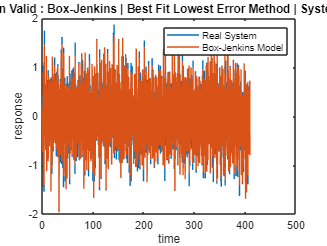


%%
figure(1)
plot(t_val,y2_val,t_val,BestFit_y_hatprbs)
legend('Real System','Box-Jenkins Model')
title(" PRBS Ident - Guassian Valid : Box-Jenkins | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

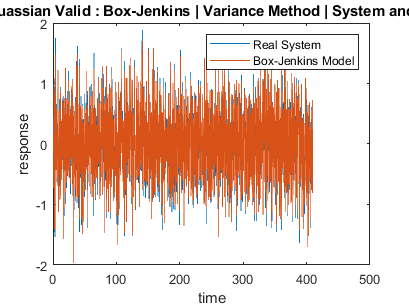


figure(2)
plot(t_val,y2_val,t_val,Var_y_hatprbs)
legend('Real System','Box-Jenkins Model')
title(" PRBS Ident - Guassian Valid : Box-Jenkins | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

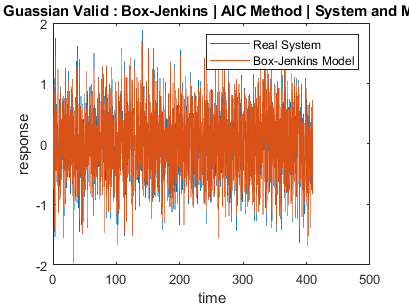


figure(3)
plot(t_val,y2_val,t_val,AIC_y_hatprbs)
legend('Real System','Box-Jenkins Model')
title(" PRBS Ident - Guassian Valid : Box-Jenkins | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

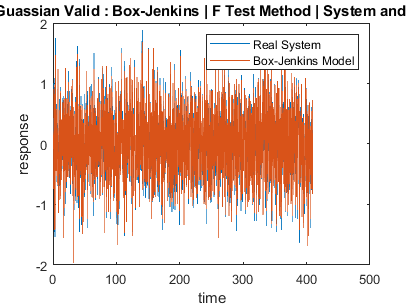


figure(4)
plot(t_val,y2_val,t_val,FTest_y_hatprbs)
legend('Real System','Box-Jenkins Model')
title(" PRBS Ident - Guassian Valid : Box-Jenkins | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

% 
% %%
% 
% figure(5)
% subplot(4,1,1)
% plot(1:N_val-1,bj_BestFit_Reeprbs(2:end), 1:N_val-1, mean(bj_BestFit_Reeprbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Box-Jenkins | Best Fit Lowest Errror Method | Reeprbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Reeprbs(k)")
% 
% subplot(4,1,2)
% plot(1:N_val-1,bj_Var_Reeprbs(2:end), 1:N_val-1, mean(bj_Var_Reeprbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Box-Jenkins | Variance Method | Reeprbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Reeprbs(k)")
% 
% subplot(4,1,3)
% plot(1:N_val-1,bj_AIC_Reeprbs(2:end), 1:N_val-1, mean(bj_AIC_Reeprbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Box-Jenkins | AIC Method | Reeprbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Reeprbs(k)")
% 
% subplot(4,1,4)
% plot(1:N_val-1,bj_FTest_Reeprbs(2:end), 1:N_val-1, mean(bj_FTest_Reeprbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Box-Jenkins | F Test Method | Reeprbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Reeprbs(k)")
% 
% %%
% 
% figure(6)
% subplot(4,1,1)
% plot(1:N_val-1,bj_BestFit_Rueprbs(2:end), 1:N_val-1, mean(bj_BestFit_Rueprbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Box-Jenkins | Best Fit Lowest Errror Method | Rueprbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rueprbs(k)")
% 
% subplot(4,1,2)
% plot(1:N_val-1,bj_Var_Rueprbs(2:end), 1:N_val-1, mean(bj_Var_Rueprbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Box-Jenkins | Variance Method | Rueprbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rueprbs(k)")
% 
% subplot(4,1,3)
% plot(1:N_val-1,bj_AIC_Rueprbs(2:end), 1:N_val-1, mean(bj_AIC_Rueprbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Box-Jenkins | AIC Method | Rueprbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rueprbs(k)")
% 
% subplot(4,1,4)
% plot(1:N_val-1,bj_FTest_Rueprbs(2:end), 1:N_val-1, mean(bj_FTest_Rueprbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Box-Jenkins | F Test Method | Rueprbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rueprbs(k)")




